% setup
clear;
handle = load("initial_data\initial_handle.mat");
seat = load("initial_data\initial_seat.mat");


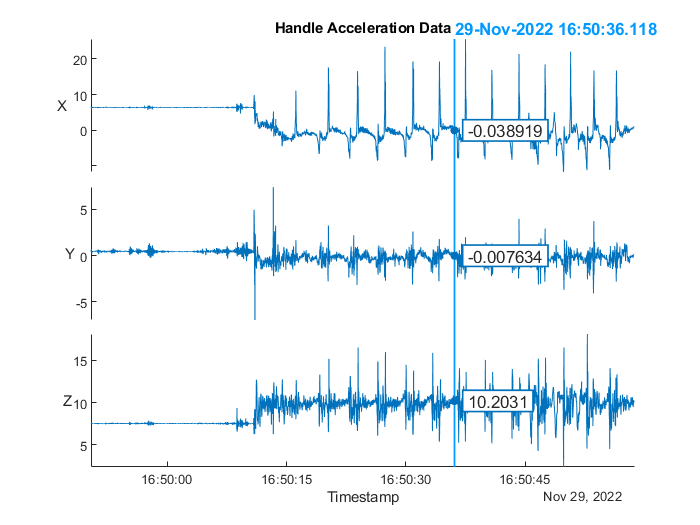

% PLOTTING ACCELERATION DATA
% handle acceleration
clf;
stackedplot(handle.Acceleration);
title("Handle Acceleration Data")

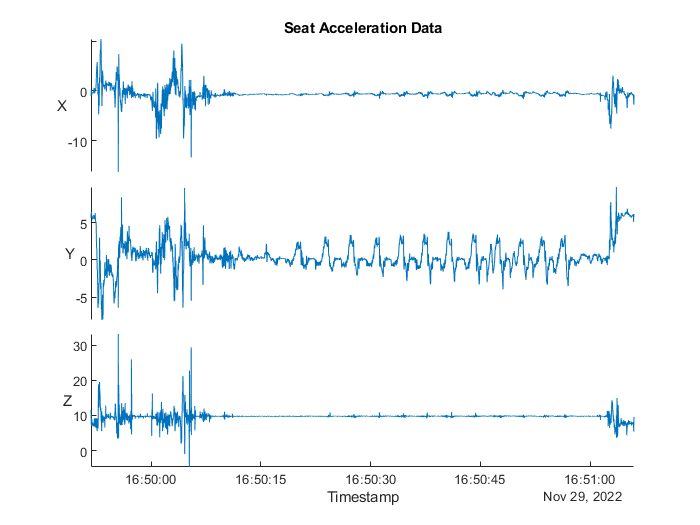


% seat acceleration 
clf;
stackedplot(seat.Acceleration);
title("Seat Acceleration Data")

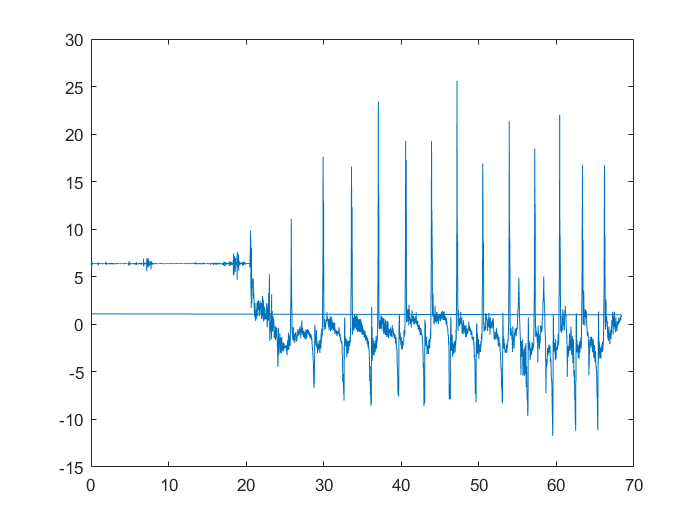

% plotting all x acceleration handle data
handle_acc = handle.Acceleration{:,1};

fs = 50;
time_all = [1:length(handle_acc)-1, 1]./fs';

clf;
plot(time_all, handle_acc);

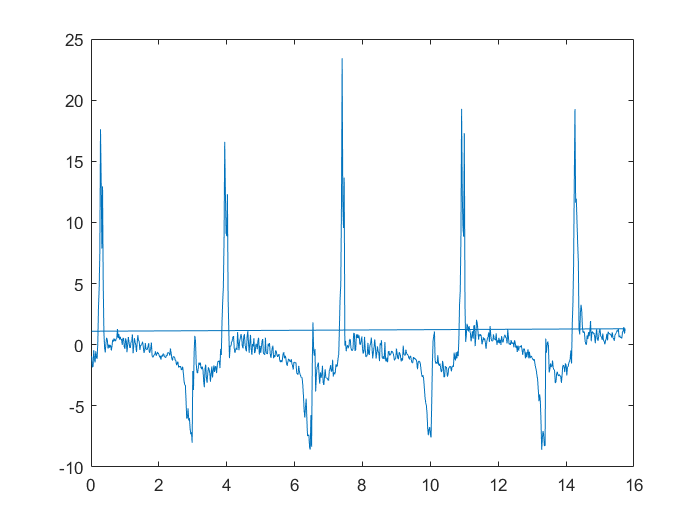


% plotting good x acceleration handle data
handle_acc_good = handle_acc(1483:2270);

fs = 50;
time_good = [1:length(handle_acc_good)-1, 1]./fs';

clf; 
plot(time_good, handle_acc_good);

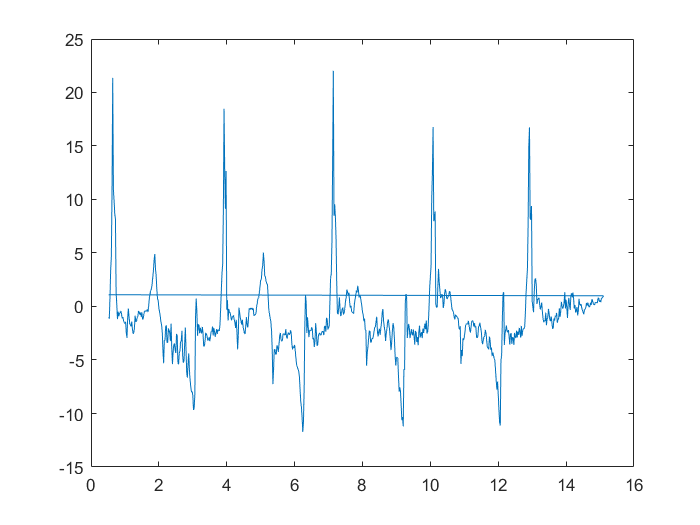


% plotting bad x acceleration handle data
handle_acc_bad = handle_acc(2690:end);

clf;
fs = 50;
time_bad = [1:length(handle_acc_bad)-1, 1]./fs';
plot(time_bad+.5, handle_acc_bad);

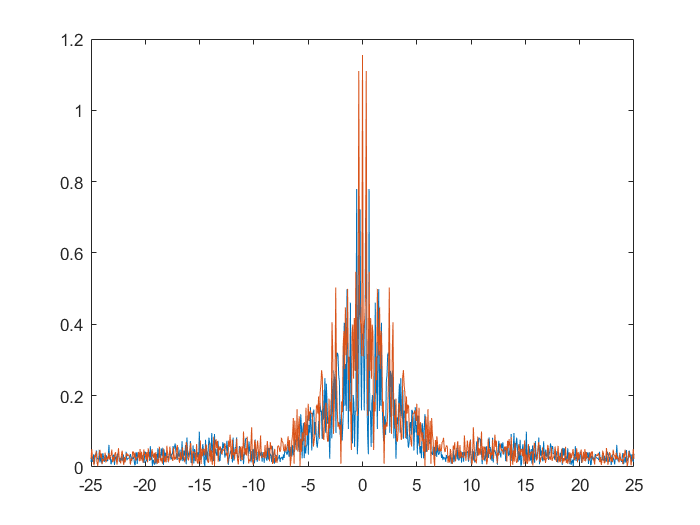

% dft of handle acceleration of good rowing section
fs = 50; % sampling frequency = 50

x_acc_good = handle.Acceleration{1483:2270,1};
N = length(x_acc_good);

acc_dft = fftshift(abs(fft(x_acc_good)));
frequencies = linspace(-fs/2, fs/2, N);

clf;
plot(frequencies, acc_dft/N)

% dft of handle acceleration of bad rowing section
fs = 50; % sampling frequency = 50

x_acc_bad = handle.Acceleration{2690:end,1};
N = length(x_acc_bad);

acc_dft = fftshift(abs(fft(x_acc_bad)));
frequencies = linspace(-fs/2, fs/2, N);

hold on;
plot(frequencies, acc_dft/N)